**AFSAH  HYDER**

**LAB 02**

**Activity 1**

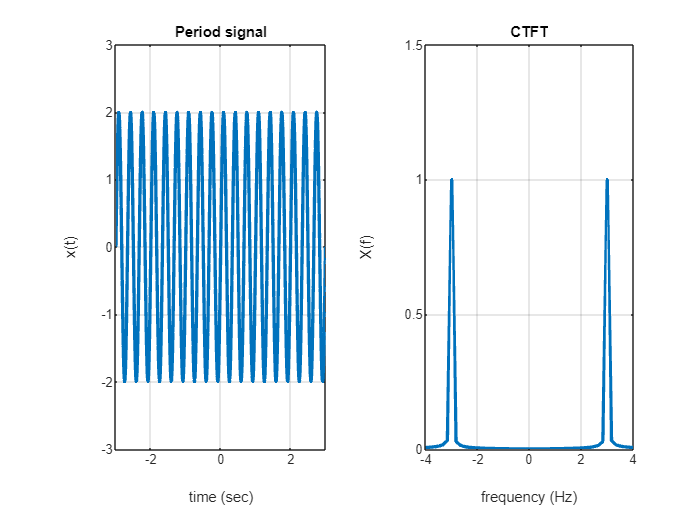

clc; clear; close all
A = 2; % Amplitude of the DC signal
tmax = 3; % (sec) Maximum time
tmin = -3; % (sec) Minimum time
Ts = 0.01; % (sec) Sampling time  
fs = 1/Ts; % (Hertz) Sampling frequency
fo = 3;
time = tmin:Ts:tmax; % (sec) Time axis
N = length(time); % Number of samples
xt1 = A*sin(2*pi*fo*time); % The signal
Xs = fft(xt1,N); % Fourier Transform of the sampled signal
X = Ts*Xs/(tmax-tmin); % Fourier Transform of the continuous signal
X = fftshift(X); % Transform is centered around f = 0
freq = linspace(-fs/2, fs/2, N); % Frequency axis
figure; subplot 121; plot(time, xt1, 'linewidth', 2);ylim([min(xt1)-1 max(xt1)+1])
xlabel('time (sec)'); ylabel('x(t)'); title('Period signal'); grid on;
subplot 122; plot(freq, abs(X), 'linewidth', 2);ylim([0 1.5]); xlim([-4 4])
xlabel('frequency (Hz)'); ylabel('X(f)');title('CTFT'); grid on;

For non periodic signal

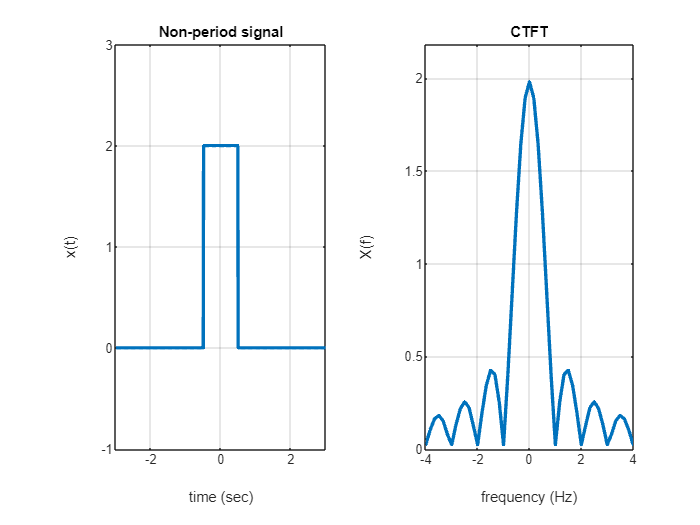

A = 2; % Amplitude of the DC signal
tmax = 3; % (sec) Maximum time
tmin = -3; % (sec) Minimum time
Ts = 0.01; % (sec) Sampling time
fs = 1/Ts; % (Hertz) Sampling frequency
tau = 1;
time = tmin:Ts:tmax; % (sec) Time axis
N = length(time); % Number of samples
xt2 = A*(abs(time) < tau/2); % The signal
Xs = fft(xt2,N); % Fourier Transform of the sampled signal
X = Ts*Xs; % Fourier Transform of the continuous signal
X = fftshift(X); % Transform is centered around f = 0
freq = linspace(-fs/2, fs/2, N); % Frequency axis
figure; subplot 121; plot(time, xt2, 'linewidth', 2);ylim([min(xt2)-1 max(xt2)+1])
xlabel('time (sec)'); ylabel('x(t)'); title('Non-period signal'); grid on;
subplot 122; plot(freq, abs(X), 'linewidth', 2);ylim([0 max(abs(X))+0.2]); xlim([-4 4])
xlabel('frequency (Hz)'); ylabel('X(f)');title('CTFT'); grid on;

Part c

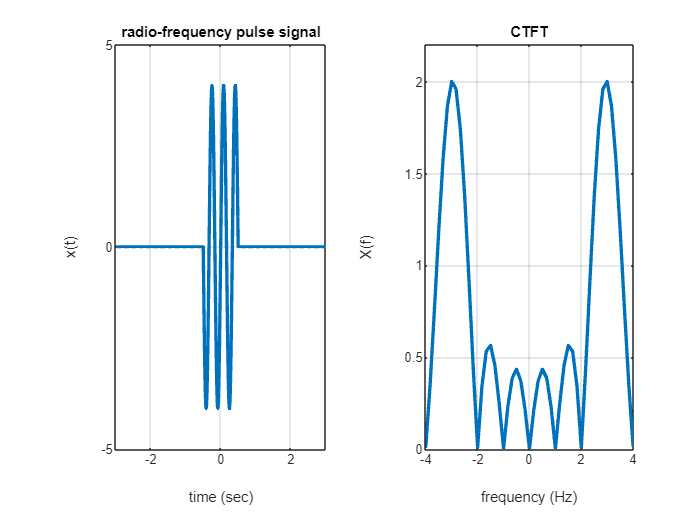

tmax = 3; % (sec) Maximum time
tmin = -3; % (sec) Minimum time
Ts = 0.01; % (sec) Sampling time
fs = 1/Ts; % (Hertz) Sampling frequency
tau = 1;
time = tmin:Ts:tmax; % (sec) Time axis
N = length(time); % Number of samples
xt3 = xt1.*xt2; % The signal
Xs = fft(xt3,N); % Fourier Transform of the sampled signal
X = Ts*Xs; % Fourier Transform of the continuous signal
X = fftshift(X); % Transform is centered around f = 0
freq = linspace(-fs/2, fs/2, N); % Frequency axis
figure; subplot 121; plot(time, xt3, 'linewidth', 2);ylim([min(xt3)-1 max(xt3)+1]);  xlim([tmin tmax])
xlabel('time (sec)'); ylabel('x(t)'); title('radio-frequency pulse signal'); grid on;
subplot 122; plot(freq, abs(X), 'linewidth', 2);ylim([0 max(abs(X))+0.2]); xlim([-4 4])
xlabel('frequency (Hz)'); ylabel('X(f)');title('CTFT'); grid on;

part d

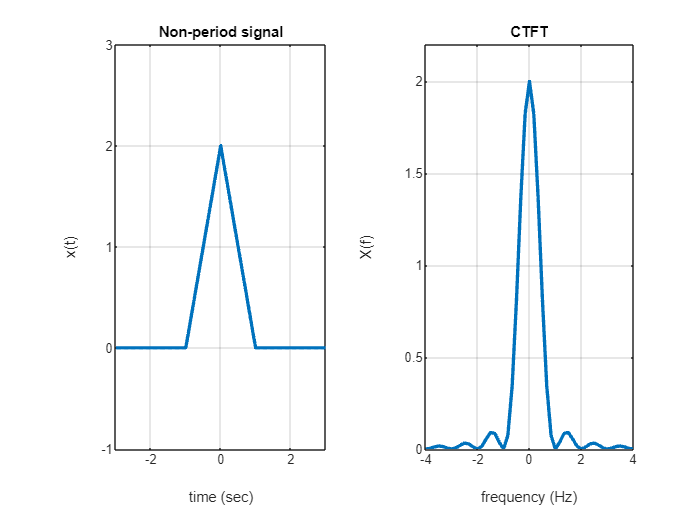

A = 2; % Amplitude of the DC signal
tmax = 3; % (sec) Maximum time
tmin = -3; % (sec) Minimum time
Ts = 0.01; % (sec) Sampling time
fs = 1/Ts; % (Hertz) Sampling frequency
tau = 1;
time = tmin:Ts:tmax; % (sec) Time axis
xt = zeros(size(time));

% Define the piecewise function
for i = 1:length(time)
    t = time(i);
    if t >= -tau && t < 0
        xt(i) = A / tau * (tau + t);
    elseif t >= 0 && t < tau
        xt(i) = A / tau * (tau - t);
    else
        xt(i) = 0;
    end
end

Xs = fft(xt,N); % Fourier Transform of the sampled signal
X = Ts*Xs; % Fourier Transform of the continuous signal
X = fftshift(X); % Transform is centered around f = 0
freq = linspace(-fs/2, fs/2, N); % Frequency axis
figure; subplot 121; plot(time, xt, 'linewidth', 2);ylim([min(xt)-1 max(xt)+1]);  xlim([tmin tmax])
xlabel('time (sec)'); ylabel('x(t)'); title('Non-period signal'); grid on;
subplot 122; plot(freq, abs(X), 'linewidth', 2);ylim([0 max(abs(X))+0.2]); xlim([-4 4])
xlabel('frequency (Hz)'); ylabel('X(f)');title('CTFT'); grid on;

**Activity 2**

**NRZ Polar**

close all;
disp("Polar NRZ");

Polar NRZ


A = 1; J = 2; M = 10; L = 20000;
sNt = [];
Bits = (sign(randn(1,2*J+1))+1)/2;
for ii=1:2*J+1
    if Bits(ii)==1
        sNt=[A*ones(1,M) sNt];
    else
        sNt=[-A*ones(1,M) sNt];
    end
end

disp(Bits)

     0     1     1     1     1



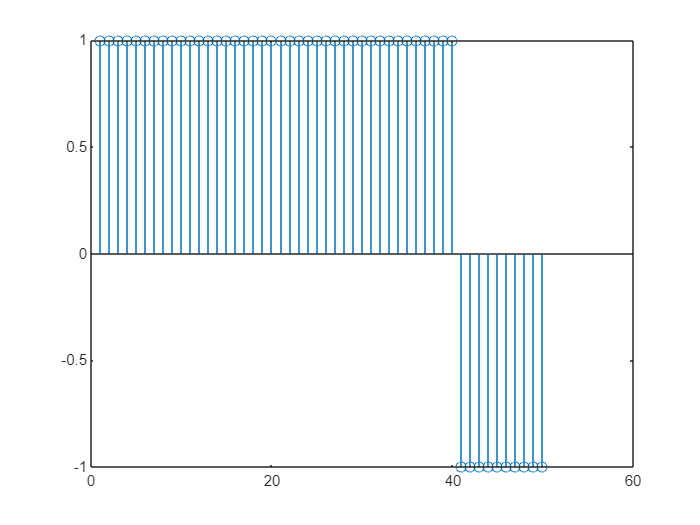

stem(sNt)

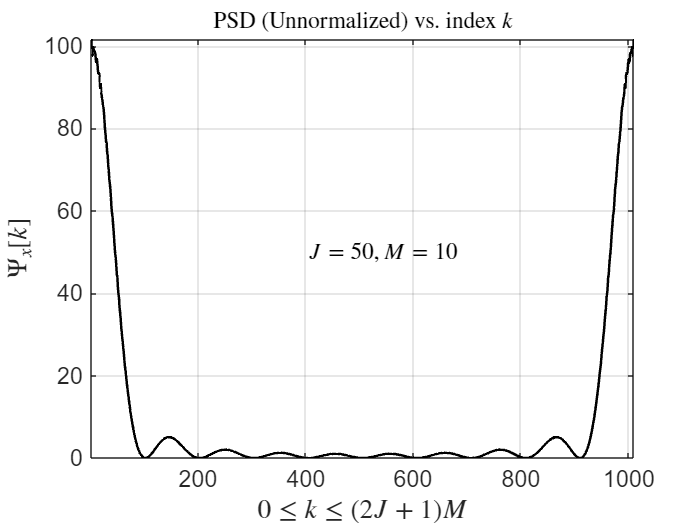

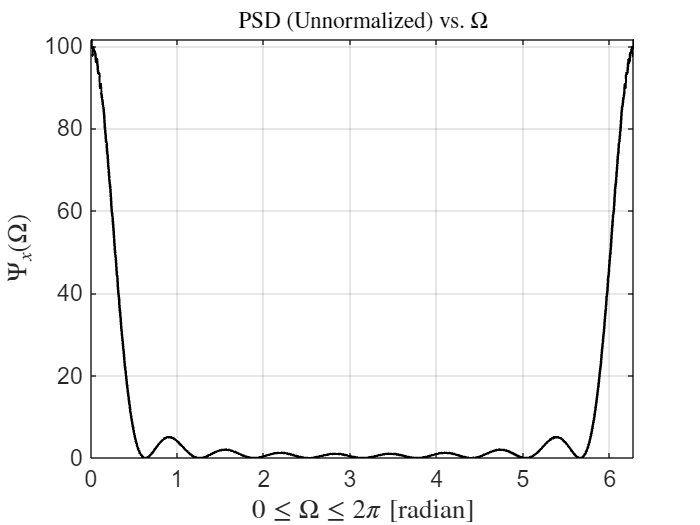

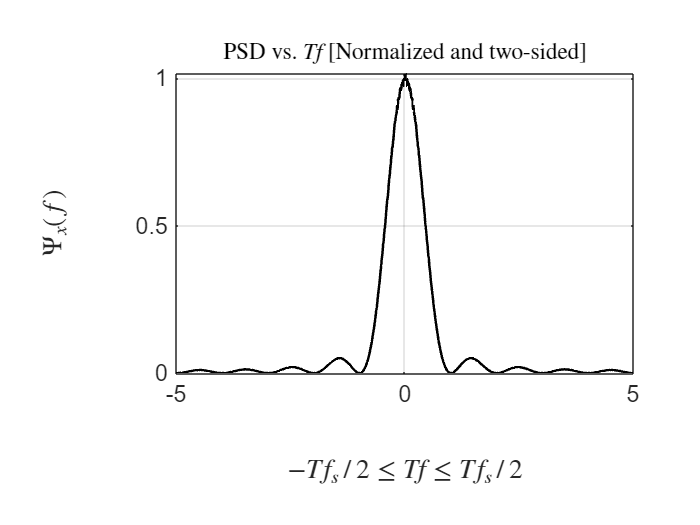

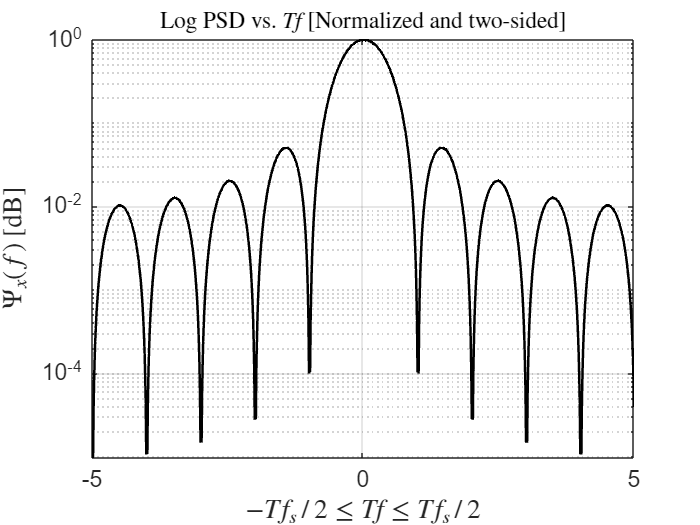


J = 50; PSD = 0;
T = 1; Ts=T/M; fs=1/Ts;
for jj=1:L
    sNt = [];
    Bits = (sign(randn(1,2*J+1))+1)/2;
    for ii=1:2*J+1
        if Bits(ii)==1
            sNt=[A*ones(1,M) sNt];
        else
            sNt=[-A*ones(1,M) sNt];
        end
    end
    PSD = PSD + abs(fft(sNt)).^2;
end
PSD_func(PSD)

**Polar RZ**

close all;
disp("Polar RZ")

Polar RZ


A = 1; J = 2; M = 10; L = 20000;
sNt = [];
Bits = (sign(randn(1,2*J+1))+1)/2;
for ii=1:2*J+1
    if Bits(ii)==1
        sNt=[A*ones(1,M/2) zeros(1,M/2) sNt];
    else
        sNt=[-A*ones(1,M/2) zeros(1,M/2) sNt];
    end
end

disp(Bits)

     0     0     0     0     1



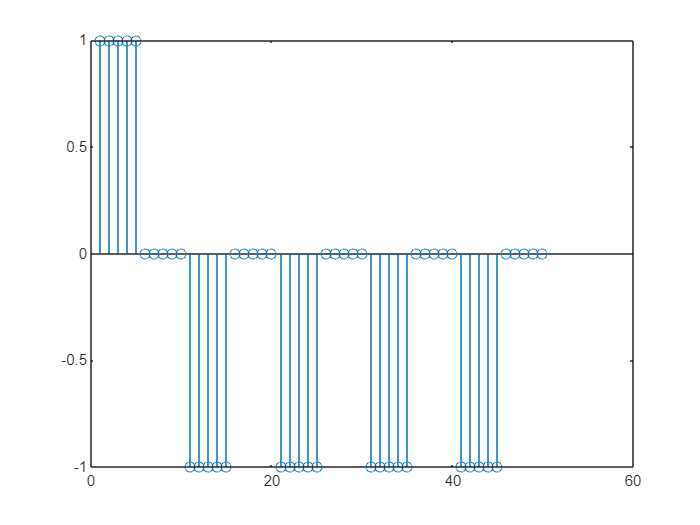

stem(sNt)

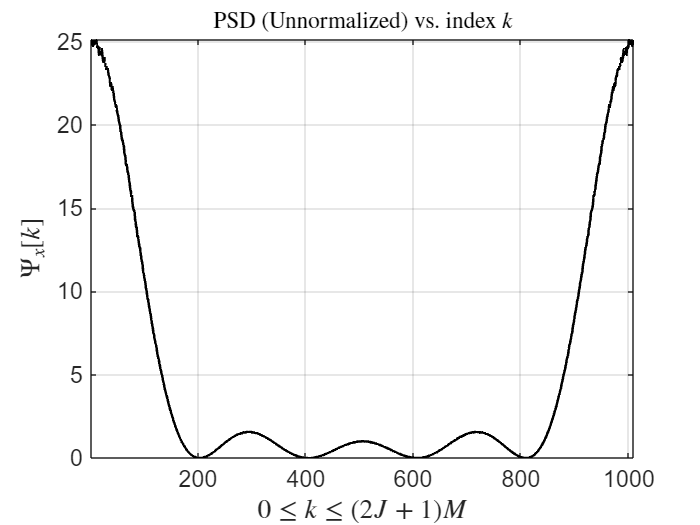

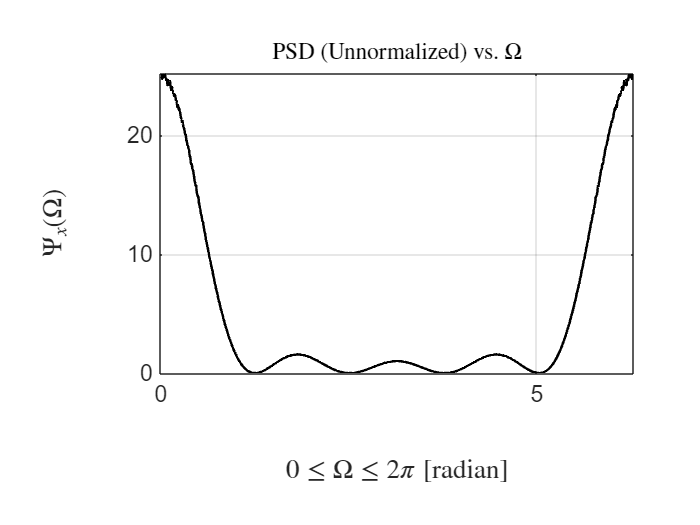

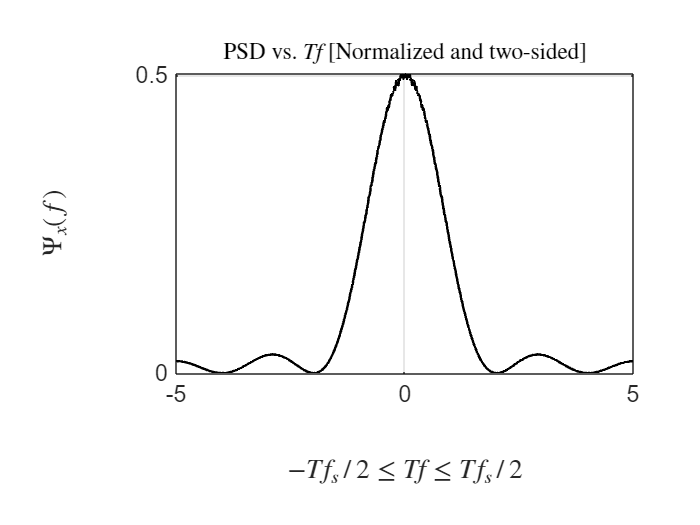

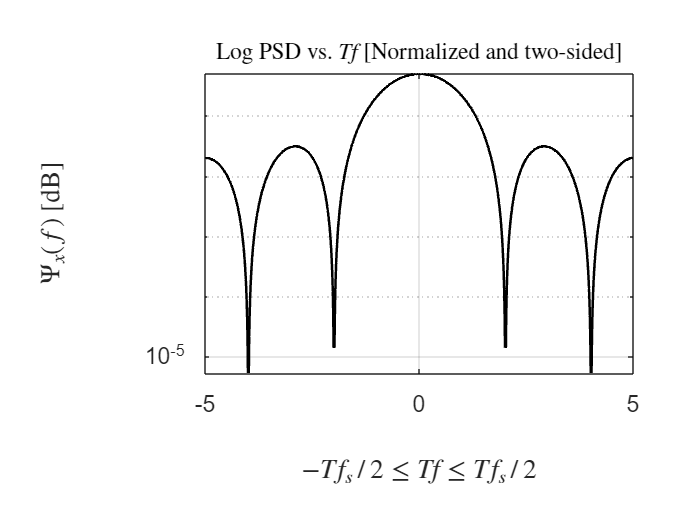


J = 50; PSD = 0;
T = 1; Ts=T/M; fs=1/Ts;
for jj=1:L
    sNt = [];
    Bits = (sign(randn(1,2*J+1))+1)/2;
    for ii=1:2*J+1
        if Bits(ii)==1
            sNt=[A*ones(1,M/2) zeros(1,M/2) sNt];
        else
            sNt=[-A*ones(1,M/2) zeros(1,M/2) sNt];
        end
    end
    PSD = PSD + abs(fft(sNt)).^2;
end

PSD_func(PSD)

**Unipolar NRZ**

close all;
disp("Unipolar NRZ");

Unipolar NRZ


A = 1; J = 2; M = 10; L = 20000;
sNt = [];
Bits = (sign(randn(1,2*J+1))+1)/2;
for ii=1:2*J+1
    if Bits(ii)==1
        sNt=[A*ones(1,M) sNt];
    else
        sNt=[zeros(1,M) sNt];
    end
end

disp(Bits)

     0     0     1     1     1



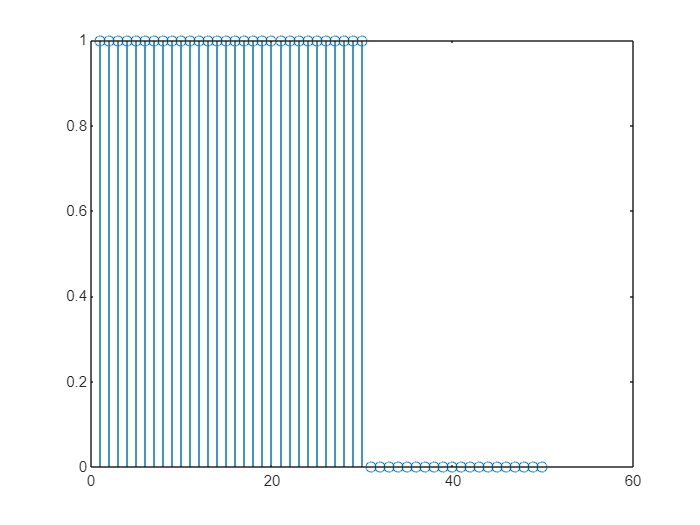

stem(sNt)

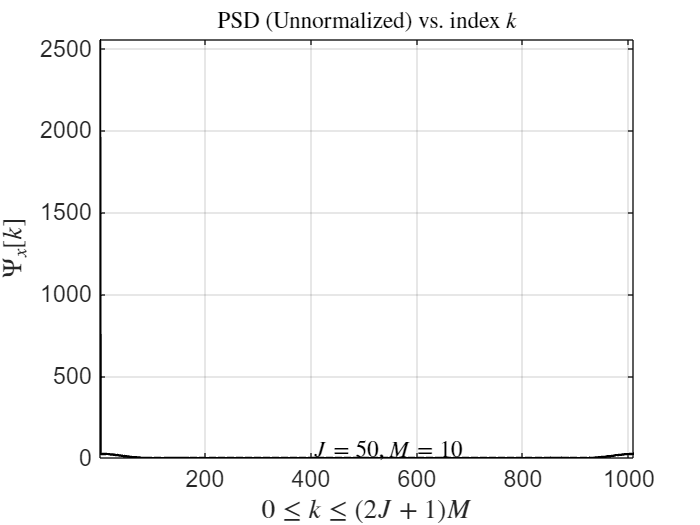

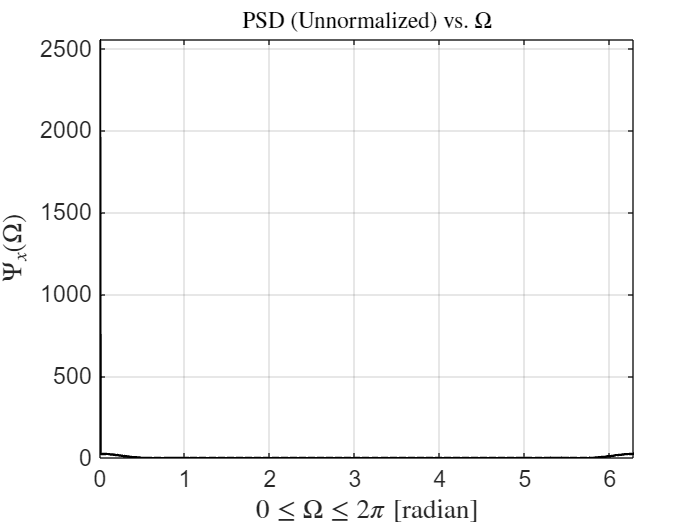

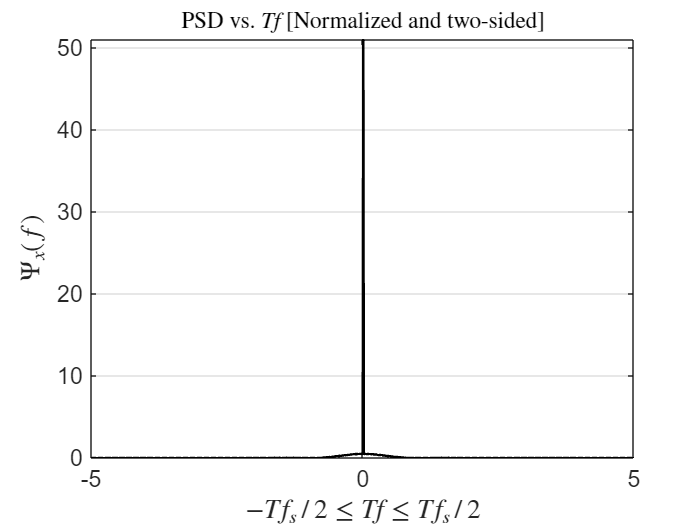

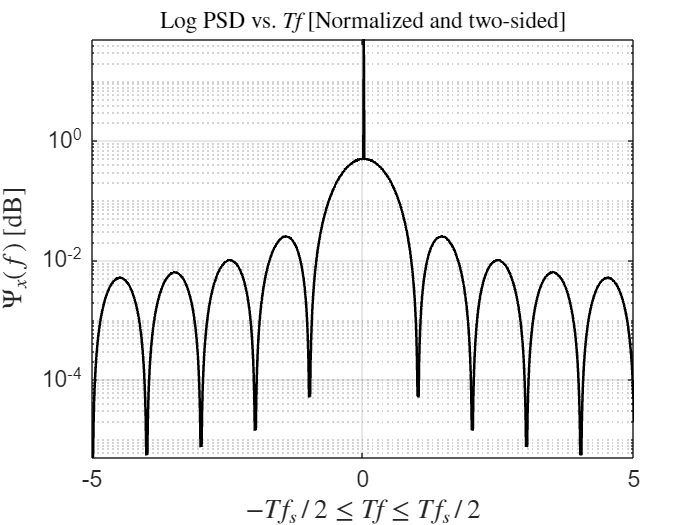


J = 50; PSD = 0;
T = 1; Ts=T/M; fs=1/Ts;
for jj=1:L
    sNt = [];
    Bits = (sign(randn(1,2*J+1))+1)/2;
    for ii=1:2*J+1
        if Bits(ii)==1
            sNt=[A*ones(1,M) sNt];
        else
            sNt=[zeros(1,M) sNt];
        end
    end
    PSD = PSD + abs(fft(sNt)).^2;
end

PSD_func(PSD)

**Unipolar RZ**

close all;
disp("Unipolar RZ");

Unipolar RZ


A = 1; J = 2; M = 10; L = 20000;
sNt = [];
Bits = (sign(randn(1,2*J+1))+1)/2;
for ii=1:2*J+1
    if Bits(ii)==1
        sNt=[A*ones(1,M/2) zeros(1,M/2) sNt];
    else
        sNt=[zeros(1,M) sNt];
    end
end

disp(Bits)

     1     0     0     1     1



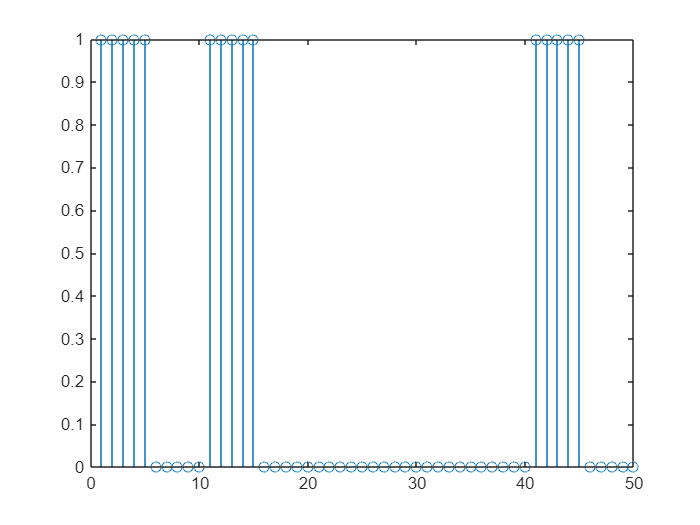

stem(sNt)

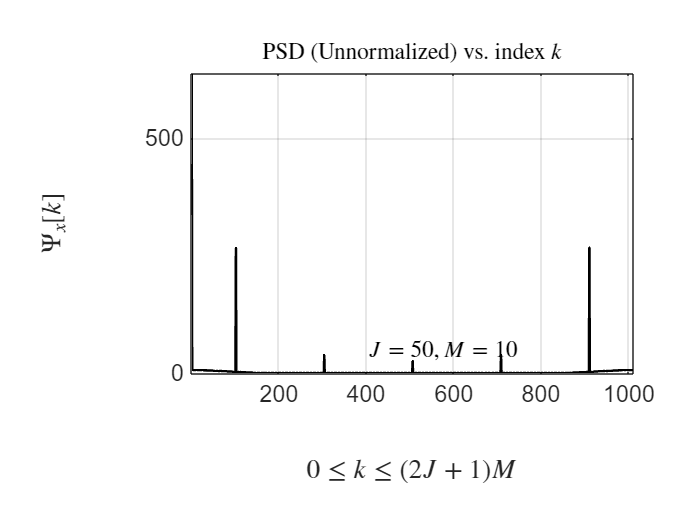

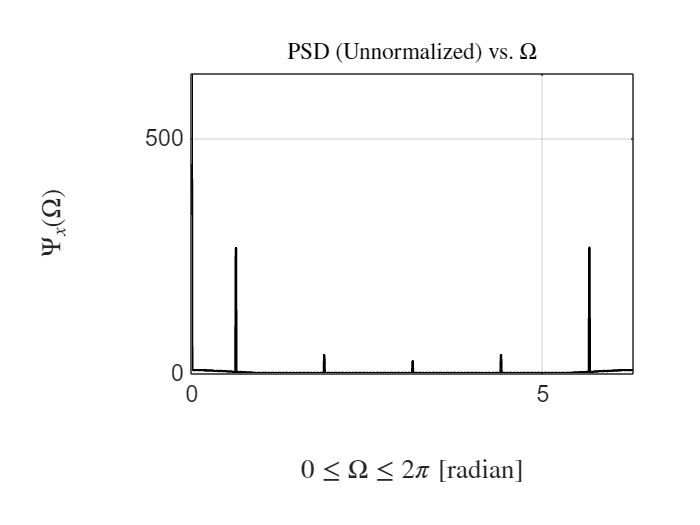

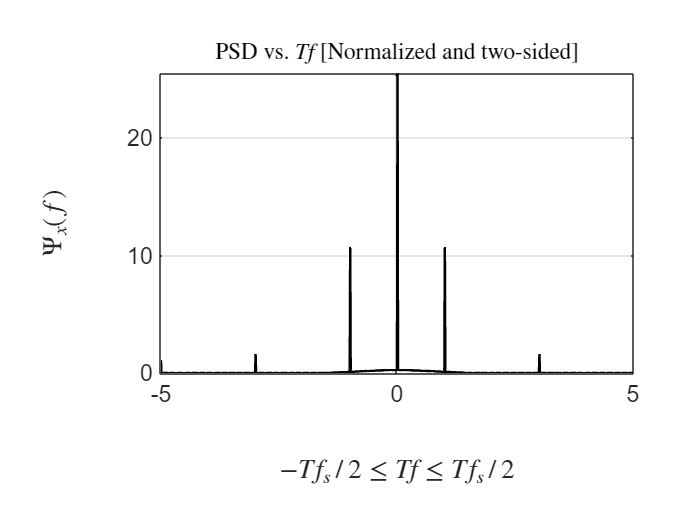

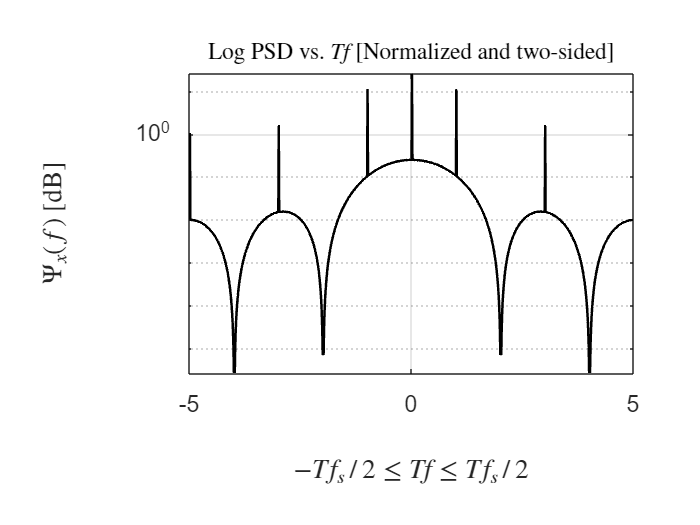


J = 50; PSD = 0;
T = 1; Ts=T/M; fs=1/Ts;
for jj=1:L
    sNt = [];
    Bits = (sign(randn(1,2*J+1))+1)/2;
    for ii=1:2*J+1
        if Bits(ii)==1
            sNt=[A*ones(1,M/2) zeros(1,M/2) sNt];
        else
            sNt=[zeros(1,M) sNt];
        end
    end
    PSD = PSD + abs(fft(sNt)).^2;
end

PSD_func(PSD)

**Bipolar NRZ**

close all;
disp("Bipolar NRZ")

Bipolar NRZ


A = 1; J = 2; M = 10; L = 20000;
sNt = [];
Bits = (sign(randn(1,2*J+1))+1)/2;
key = -1;
for ii=1:2*J+1
    if Bits(ii)==1 && key==-1
        sNt=[A*ones(1,M) sNt];
        key = 1;
    elseif Bits(ii)==1 && key==1
        sNt=[-A*ones(1,M) sNt];
        key = -1;
    else
        sNt=[zeros(1,M) sNt];
    end
end

disp(Bits)

     1     1     1     1     0



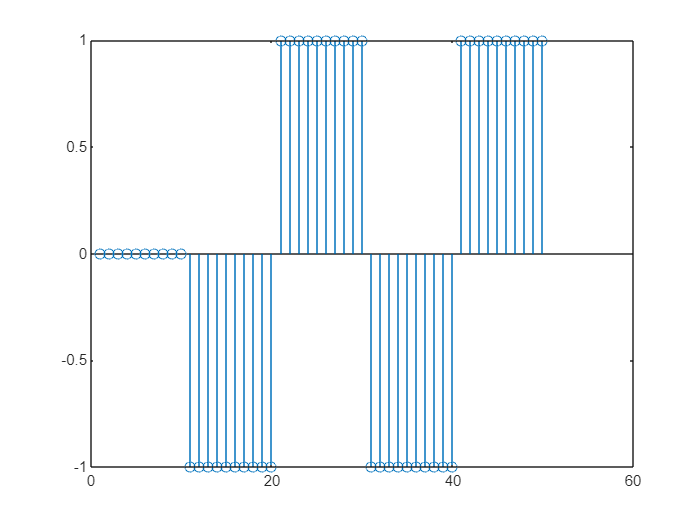

stem(sNt)

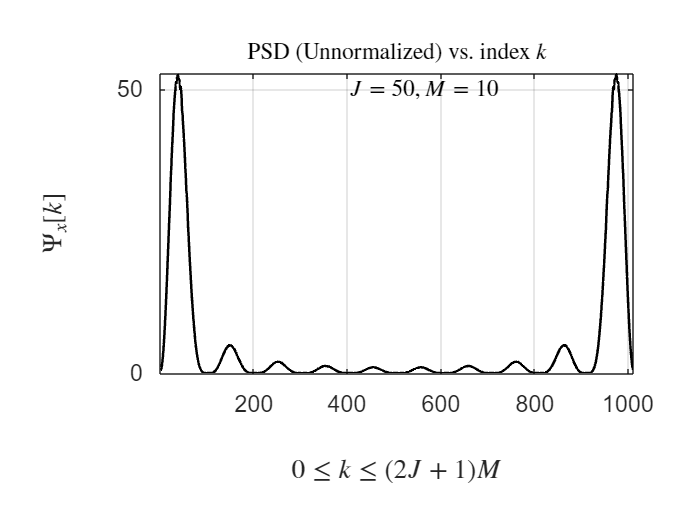

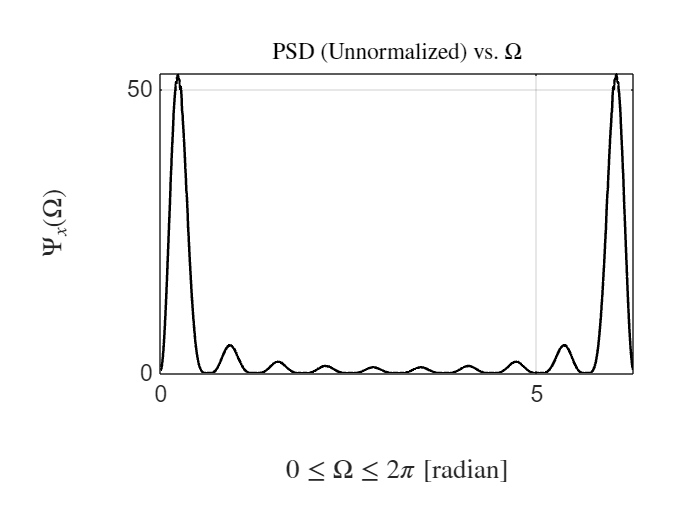

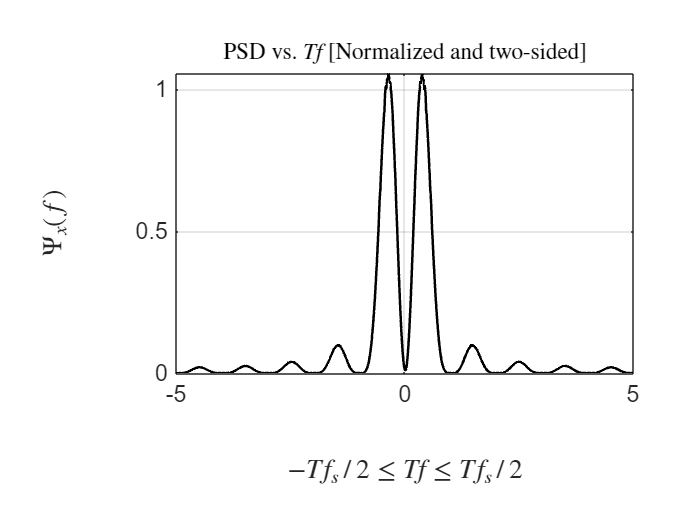

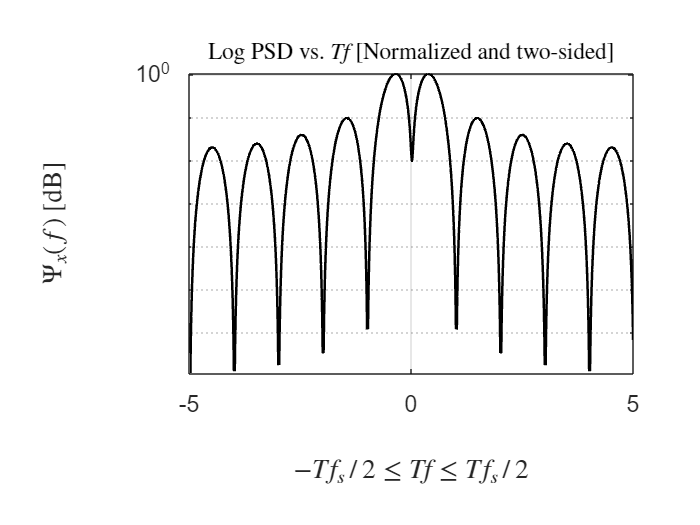


J = 50; PSD = 0;
T = 1; Ts=T/M; fs=1/Ts;
for jj=1:L
    sNt = [];
    Bits = (sign(randn(1,2*J+1))+1)/2;
    for ii=1:2*J+1
        if Bits(ii)==1 && key==-1
            sNt=[A*ones(1,M) sNt];
            key = 1;
        elseif Bits(ii)==1 && key==1
            sNt=[-A*ones(1,M) sNt];
            key = -1;
        else
            sNt=[zeros(1,M) sNt];
        end

    end
    PSD = PSD + abs(fft(sNt)).^2;
end

PSD_func(PSD)

**Bipolar RZ**

close all;
disp("Bipolar RZ");

Bipolar RZ


A = 1; J = 2; M = 10; L = 20000;
sNt = [];
Bits = (sign(randn(1,2*J+1))+1)/2;
key = -1;
for ii=1:2*J+1
    if Bits(ii)==1 && key==-1
        sNt=[A*ones(1,M/2) zeros(1,M/2) sNt];
        key = 1;
    elseif Bits(ii)==1 && key==1
        sNt=[-A*ones(1,M/2) zeros(1,M/2) sNt];
        key = -1;
    else
        sNt=[zeros(1,M) sNt];
    end
end

disp(Bits)

     0     1     1     1     1



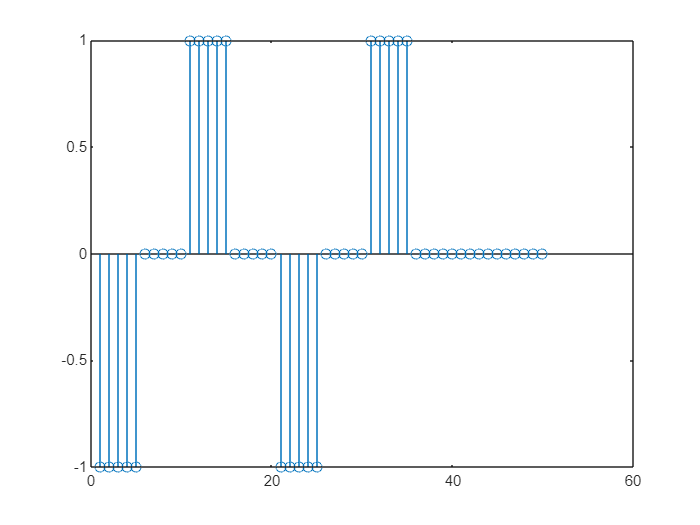

stem(sNt)

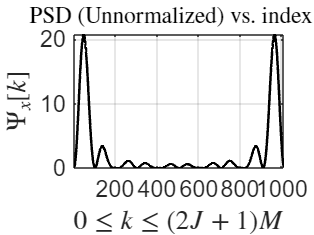

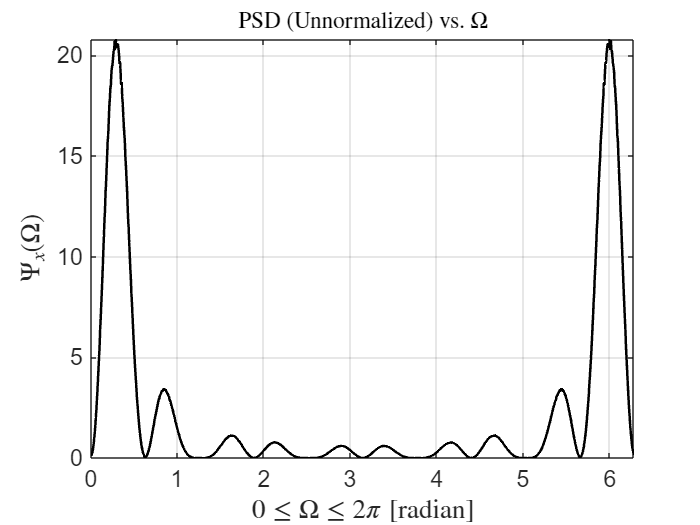

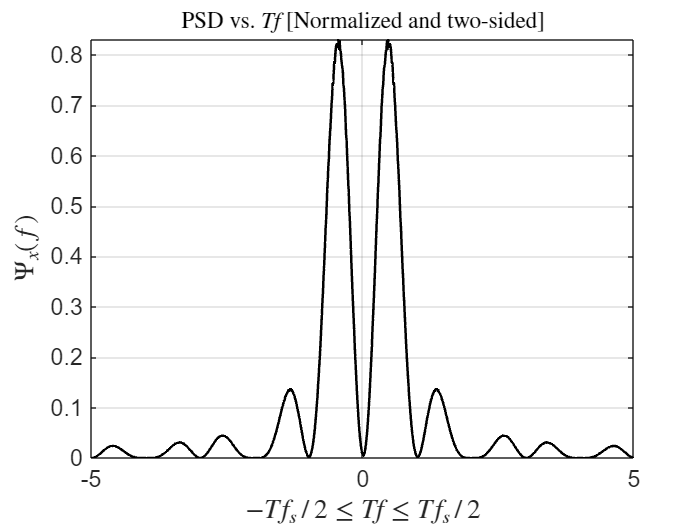

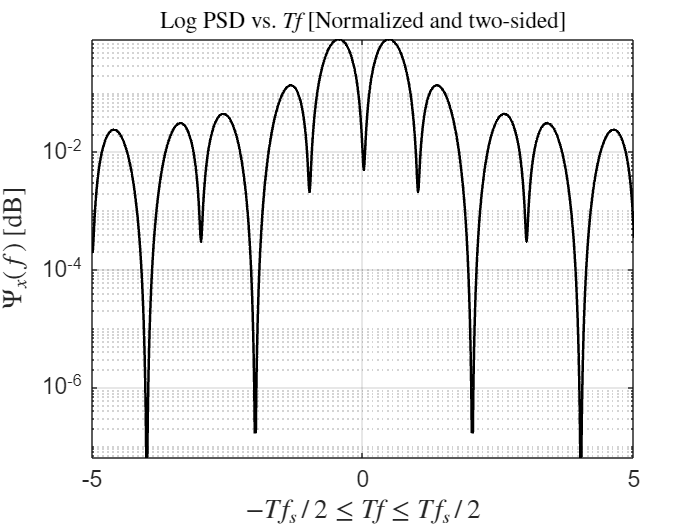


J = 50; PSD = 0;
T = 1; Ts=T/M; fs=1/Ts;
for jj=1:L
    sNt = [];
    Bits = (sign(randn(1,2*J+1))+1)/2;
    for ii=1:2*J+1
        if Bits(ii)==1 && key==-1
            sNt=[A*ones(1,M/2) zeros(1,M/2) sNt];
            key = 1;
        elseif Bits(ii)==1 && key==1
            sNt=[-A*ones(1,M/2) zeros(1,M/2) sNt];
            key = -1;
        else
            sNt=[zeros(1,M) sNt];
        end
    end
    PSD = PSD + abs(fft(sNt)).^2;
end

PSD_func(PSD)

**f) **When comparing the power spectral densities (PSDs) of different signal encoding schemes, we focus on how the frequency content of the signal spreads across frequencies, especially in the low-frequency range.

**1. ****Bipolar-NRZ Code****:**

In Bipolar-NRZ encoding, the signal alternates between positive and negative values (no zero values). This encoding method is designed to be "DC-balanced," meaning the positive and negative pulses are distributed evenly over time. Because of this balance, there is minimal low-frequency energy, and the signal doesn't have a strong DC component. When you look at its power spectral density, you'll notice it has a sharp drop-off after the Nyquist frequency (half the sampling rate), with the energy concentrated more towards the higher frequencies.

**2. ****Polar-NRZ Code****:**

Polar-NRZ works similarly to Bipolar-NRZ but with a key difference: the signal can take both positive and negative values, including zero. Because of the presence of the zero value, this encoding scheme retains some DC component, which means there's more energy in the lower frequencies. When you plot its power spectrum, you'll see a higher presence of low-frequency components compared to Bipolar-NRZ, though the decay pattern as frequency increases is still noticeable.

**3. ****Unipolar-NRZ Code****:**

In contrast, Unipolar-NRZ uses just two values: zero and positive amplitude (no negative values). This encoding method has a significant DC component because of the frequent zeros in the signal. As a result, the power spectrum will show a strong peak at very low frequencies, reflecting the DC bias. The decay of the spectrum will be slower, meaning the signal retains more energy in the lower frequencies compared to both Bipolar-NRZ and Polar-NRZ.

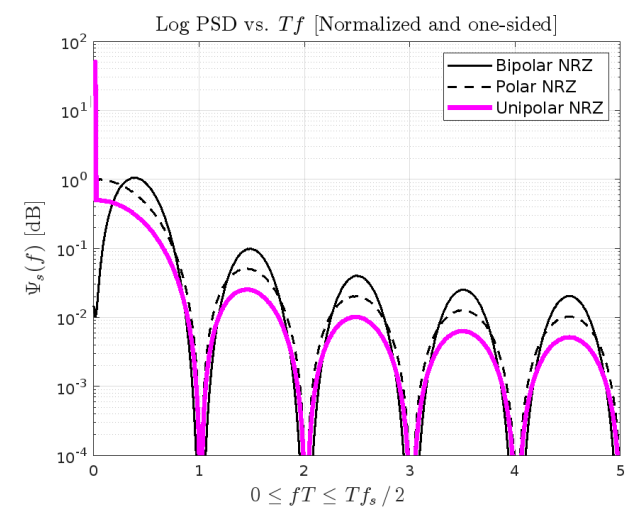

(taken from the manual, bcs similar plot was obtained indiviually)

**Observing the plots:**

- **Bipolar-NRZ**: The plot shows a sharp falloff after the Nyquist frequency. It starts with some energy around the Nyquist limit, but this energy quickly drops off, with very little contribution at low frequencies.

- **Polar-NRZ**: The plot starts similarly to Bipolar-NRZ, but it stays higher in the lower frequencies due to the DC component. Still, like Bipolar-NRZ, it eventually shows a decline in higher frequencies, though not as steep as the Bipolar-NRZ.

- **Unipolar-NRZ**: This plot looks different. It shows a large peak at low frequencies (the DC component) and then taper off more gradually as you move to higher frequencies. The spectrum decays slower compared to both Bipolar-NRZ and Polar-NRZ, thanks to the strong presence of low-frequency energy.

In simple terms, **Bipolar-NRZ** has the least low-frequency content, **Polar-NRZ** has a bit more, and **Unipolar-NRZ** has the most, with a noticeable peak at the lowest frequencies.

**g) **When comparing the power spectral densities (PSDs) of Bipolar-RZ, Polar-RZ, and Unipolar-RZ codes, we observe how the frequency content of these signals is distributed, particularly in the context of encoding schemes that are used in digital communication systems. Each of these encoding methods is designed to transmit binary data in different ways, and this results in different power spectral characteristics.

**1. ****Bipolar-RZ Code****:**

In Bipolar-RZ encoding, each bit is represented by a pulse that alternates between positive and negative voltages, with each pulse returning to zero within the bit period. This encoding is designed to ensure that the signal has no DC component, as the positive and negative pulses cancel out over time. Due to the alternating nature and return-to-zero property, the frequency spectrum of Bipolar-RZ shows:

- **Sharp cut-off**: The power is concentrated around the Nyquist frequency with significant energy at higher frequencies.

- **Low-frequency attenuation**: The signal has no DC component, so the energy at lower frequencies is very low.

The plot of Bipolar-RZ typically shows a steep falloff after the Nyquist frequency (half the symbol rate), with less low-frequency content.

**2. ****Polar-RZ Code****:**

Polar-RZ encoding, similar to Bipolar-RZ, uses return-to-zero signaling, but instead of alternating between positive and negative values, it uses two levels: one positive and one zero voltage level. The zero level acts as a return-to-zero, while the positive voltage represents the binary "1."

- **DC component**: Since it uses a zero voltage level, there are some low-frequency content (due to the zeros), but not as much as in Unipolar-RZ.

- **Steep roll-off**: Like Bipolar-RZ, it has a relatively steep falloff in the higher frequencies, though the presence of the zero level adds a little more energy at low frequencies compared to Bipolar-RZ.

Polar-RZ’s PSD plot shows higher low-frequency components than Bipolar-RZ but still decays quickly at higher frequencies.

**3. ****Unipolar-RZ Code****:**

In Unipolar-RZ encoding, the signal uses only one positive voltage level and zero to represent the binary data. The "1" is represented by a pulse at the positive level, and the "0" is represented by a zero voltage level, with the signal returning to zero after each bit period.

- **Strong DC component**: The use of zeros at regular intervals means that Unipolar-RZ has a substantial amount of energy in the low-frequency range, with a clear peak at zero frequency.

- **Slower roll-off**: Since the signal has a DC component and the frequency content is concentrated in the lower frequencies, the power spectrum decays more slowly than both Bipolar-RZ and Polar-RZ.

Unipolar-RZ’s PSD will have a sharp peak at low frequencies, then slowly decay at higher frequencies, maintaining more energy in the lower frequencies.

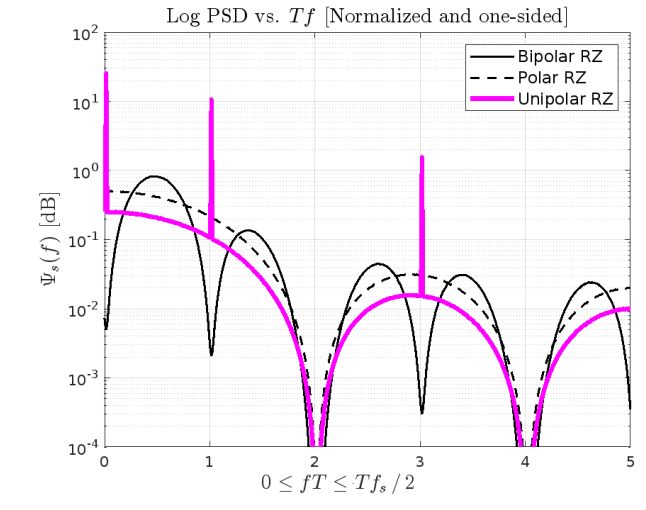

**Observing Plots:**

Here’s a conceptual overview of what the plots of the power spectral density (Ψx(f)) for each of these encoding schemes would look like when normalized on a semilogarithmic scale:

- **Bipolar-RZ**: The plot shows a rapid drop-off in power after the Nyquist frequency, with little to no low-frequency content.

- **Polar-RZ**: The plot shows more energy in the low-frequency range than Bipolar-RZ, with a relatively sharp decline at higher frequencies.

- **Unipolar-RZ**: The plot has a noticeable peak at low frequencies (near zero), representing the strong DC component, followed by a slower falloff as frequency increases.

**h) **Polar NRZ comparision:

**Simulation**

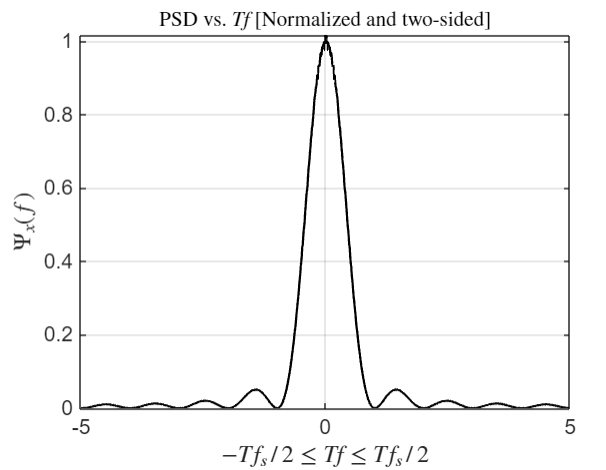

**Theoretical:**

T= 1 in the code, so the magnitude of wave at Tf=0, is 1..since sinc^2 = 1.

**Polar RZ**

**Theoretical:**

**Simulation:**

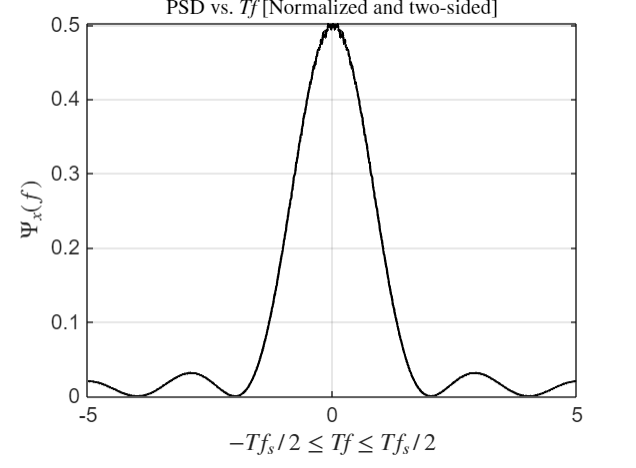

T = 1 , so amplitude at Tf= 0 ..is Ts/2 (As in the equation) i.e. 0.5.

## **Activity 3**

**1. ****Potential Drawbacks of DC Voltage in Data Transmission**

Including DC voltage in data transmission can lead to several drawbacks:

- **DC Wander**: Prolonged constant voltage levels can shift the baseline, making it harder to distinguish signal levels at the receiver.

- **Inefficient Power Use**: DC components consume power without aiding data transmission, reducing overall efficiency.

- **Transmission Challenges**: DC signals are blocked by components like transformers and AC-coupled circuits, causing signal distortion.

- **Increased Complexity**: Compensating for DC voltage may require extra circuitry, adding to system complexity.

**2. ****Advantages and Disadvantages of RZ Compared to NRZ**

**Advantages of RZ**:

- Easier clock recovery due to the signal returning to zero in each bit period.

- Reduced inter-symbol interference (ISI) because of the periodic reset.

**Disadvantages of RZ**:

- Requires more bandwidth due to frequent transitions.

- Consumes more power because of additional signal changes.

- More complex to generate and decode compared to NRZ.

**3.  ****Spectral Null at f****=****0**** in Bipolar Codes: Advantage or Disadvantage?**

**Advantages**:

- **No DC Component**: The absence of a DC component improves compatibility with AC-coupled systems like transformers and other transmission media.

- **Error Detection**: Bipolar codes naturally support error detection because any polarity error disrupts the alternating pattern.

**Disadvantages**:

- **Higher Complexity**: Bipolar coding is harder to implement and decode compared to simpler polar codes.

- **Slightly Lower Efficiency**: Polarity switching may slightly increase power usage compared to simpler schemes.

Overall, the spectral null at f=0 is beneficial as it enhances signal reliability and compatibility with various hardware systems.

**4. **

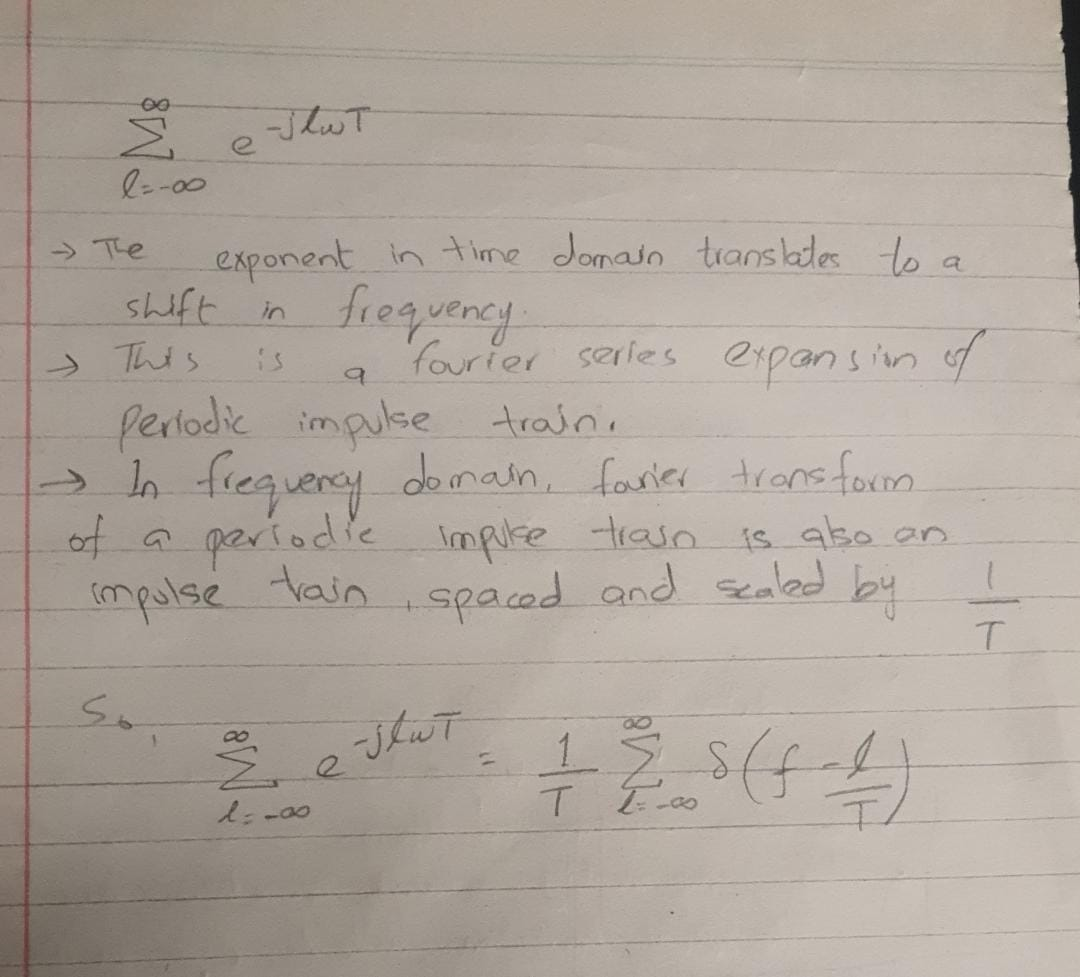

**5.**

The multiplication by Ts^2 comes from the relationship between the **DFT** and the **CFT**.

- When we sample a continuous signal, the DFT gives a discrete set of frequency components, and those components are spaced by 1/Ts, where Ts is the sampling period.

- The scaling factor Ts^2� compensates for the differences in amplitude and frequency scaling between the discrete and continuous frequency representations.

Thus, multiplying by Ts^2� ensures that the amplitude and the frequency spacing of the discrete spectrum align correctly with the continuous spectrum, allowing you to numerically approximate the continuous Fourier transform Ψx(f) from the discrete transform Ψx[k].

**6. Synchronization Issues in Unipolar and Bipolar Codes**

**Unipolar Codes**:

Unipolar codes use a single voltage level, with binary 1 represented by a positive voltage and binary 0 by zero voltage. Synchronization issues arise during long sequences of identical values (e.g., consecutive 1s or 0s), as the lack of transitions makes it difficult for the receiver to maintain timing. The presence of a DC component also complicates clock recovery.

**Bipolar Codes**:

Bipolar codes alternate the polarity for binary 1s and use zero voltage for binary 0s. This alternation removes the DC component, improving synchronization compared to unipolar codes. However, long runs of 0s can still cause synchronization challenges due to the absence of transitions. While bipolar codes are better for timing recovery, they still rely on regular transitions to maintain synchronization.

**7. Understanding Dicode NRZ**

Dicode NRZ is a coding method that represents data through changes in signal levels rather than absolute voltage values. A binary 1 is indicated by a level transition, while a binary 0 is represented by no change in the level.

**Key Features**:

- Eliminates DC components, making it compatible with AC-coupled systems.

- Provides better synchronization by using transitions to help the receiver align its clock.

- Makes error detection easier, as any disruptions in the sequence are noticeable.

Dicode NRZ is ideal for high-speed data transmission where both efficient bandwidth use and reliable synchronization are important..